Assignment 1

rng(10)
addpath('functions')

A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];

eigs = roots(A)

eigs =    0.9902 + 0.0000i
   0.9947 + 0.0000i
   0.9480 + 0.0005i
   0.9480 - 0.0005i


abs(eigs)

ans =     0.9902
    0.9947
    0.9480
    0.9480


%% System Parameters
N = 1000;  % Number of time steps
sigma_e = 0.1;  % Standard deviation of process noise
k = 1;  % Input delay
alpha = 0.5; % Gain for P ctrl

% Setpoint(SP) (constant [1], step change [2] or square wave [3])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3])
SP = 3;
Stochastic = 1;
ctrl = 3;
switch SP
    case 1
        omega = zeros(N,1); % Constant reference setpoint
    case 2
        omega = ones(N,1);
    case 3
        T = N/2; % Periode in sampels
        omega = square(2*pi*1/T*(1:N),50)';
    otherwise
        msg = "Choose a valid value for: Setpoint";
        error(msg)
end

switch Stochastic
    case 1
        e = sigma_e * randn(N, 1);  % Process noise (Gaussian)
    case 2
        e = zeros(N,1)
    otherwise
        msg = "Choose a valid value for: Stochastic";
        error(msg)
end


switch ctrl
    case 1
        [y,u] = Pctrl(A, B, alpha, omega, e*0, N, k);
    case 2
        [y,u] = MV(A, B, e, N, k);
    case 3
        [y,u] = MV0(A, B, omega, e, N, k);
    otherwise
        msg = "Choose a valid value for: Control type";
        error(msg)
end



disp("y_mean  = " + mean(y(end/2:end)))

y_mean  = -0.0028624


disp("y_var  = " + var(y(end/2:end)))

y_var  = 1.0123


disp("u_mean  = " + mean(u(end/2:end)))

u_mean  = 47.2262


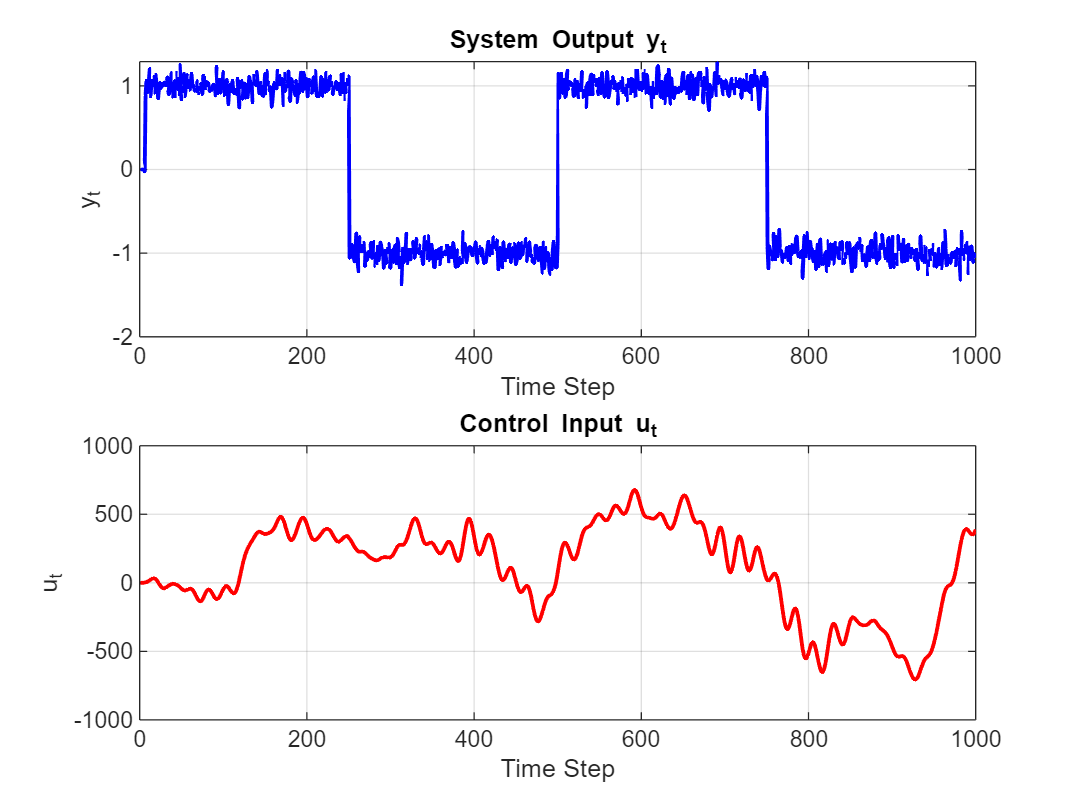


%% Plot Results
figure;
subplot(2,1,1);
plot(y, 'b', 'LineWidth', 1.5);
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;

subplot(2,1,2);
plot(u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

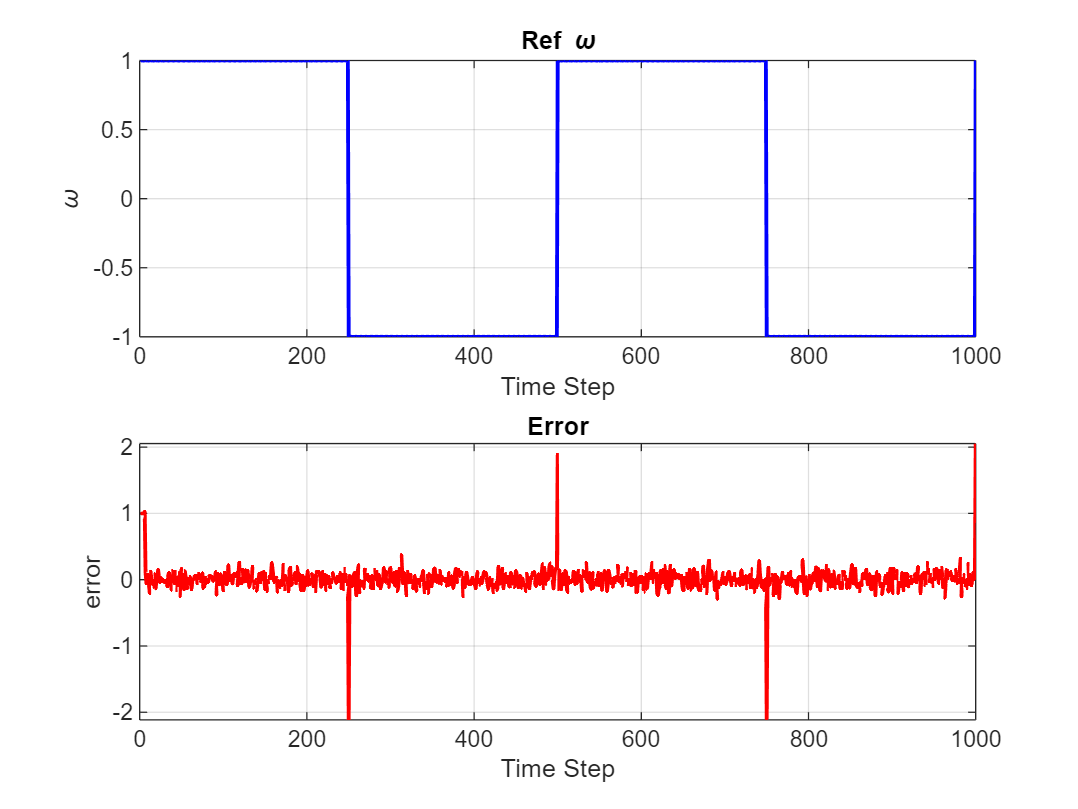


figure
subplot(2,1,1)
plot(omega, 'b', 'LineWidth', 1.5);
title('Ref \omega');
% ylim([-max(omega)*1.2,max(omega)*1.2])
xlabel('Time Step');
ylabel('\omega');
grid on;
subplot(2,1,2)
plot(omega-y, 'r', 'LineWidth', 1.5);
title('Error');
xlabel('Time Step');
ylabel('error');
grid on;